# Population Tooling - Study Demo

In this document, the steps for doing a study using the population tooling are discussed. The goal of the population tooling is to simplify and automate studies, such that they no longer require a large amount of manual steps. 

In this livescript, we go through the process steps starting from having the rerun or self-corrected datasets to creating a powerpoint with plots relevant for analysis during the study. Thus, this livescript combines the information from the demoPlots and demoPPT livescript. More information on how to rerun or self-correct the datasets can be found in the rerun- or self correction script on the sharedrive. (In the future livescripts will be made of these aswell.)

The Rerun script and the Selfcorrection script may be found in \\asml.com\eu\shared\nl011052\BMMO_NXE_TS\01-Functional\Tools\SelfCorrection_and_Rerun_scripts

## Getting started

First of all, we load the data. Normally, the datasets contain many, many jobs resulting in very large datasets. For now, we load in just a few of these datasets to make everything accesible.

file_dir = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\';
load([file_dir 'reRunOutputs_reduced_data_AF26'])

This gives us 3 output structures:

- lot_dates:            The dates and times at which the jobs were performed. This is an input (lotDates) for many functions in the population tooling.

- reRunOutputs     The data from rerun and self correction simulations. This is referred to in the functions as simOutputs.

- sort_Id                 The order in which the data of the jobs is loaded.

Next, the population tooling 'modules' are imported and the ppt is initialized. The machineId is extracted from the loaded results and the pptPath and pptName is defined. These properties are then attributed to the ppt or new slides in the powerpoint for the case of insertChapter.

import BMMO_XY.populationTooling.PPT
import BMMO_XY.populationTooling.tools.*
import BMMO_XY.populationTooling.plots.*
import BMMO_XY.populationStudy.kpi.*

pptName = 'DemoStudy';
pptPath = pwd;
machineId = reRunOutputs(1).bmmoInputsRecorrected.info.F.machine_id;
simulationType = 'rerun';

ppt = PPT(pptName, pptPath);
ppt.setTitle('Demo population study');
ppt.insertChapter(['Machine: ' machineId ' ' simulationType]);

## Plotting the Data

The next step is to plot the data in figures and place the figures into the ppt. The function modelOutputDecomposition generates 2 figures (1 per chuck), both containing trend line plots of the 99.7 percentile of the uncontrolled overlay values and total filtered correction overlay values. The figures also contain trend bar plots of the 99.7 percentile of the overlay values of the KA, BAO, MI, INTRAF and SUSD corrections. Ofcourse, other functions of the population study tooling can be used to extract relevant information, as well as other functions in the toolbox, although the inputs or outputs of the latter may not be always fully compatible. 

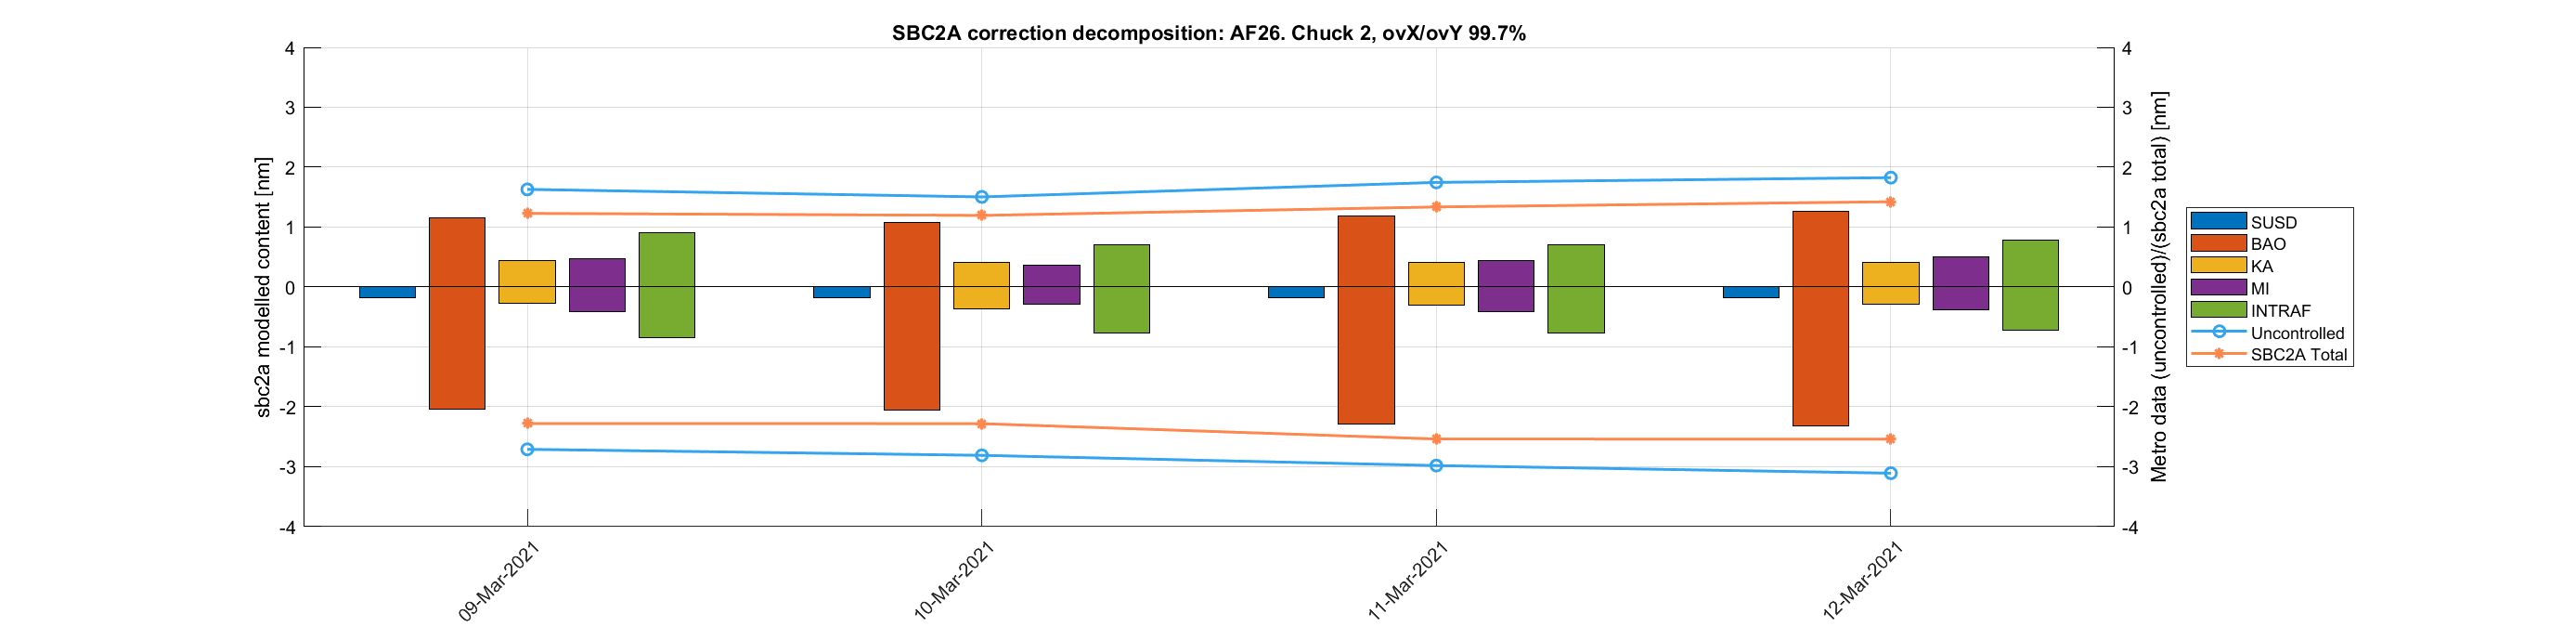

figs = modelOutputDecomposition(reRunOutputs, lot_dates, machineId);
setYaxis(figs, 'left', -4, 4);
setYaxis(figs, 'right', -4, 4);
ppt.insertFigures('Model Output Decomposition', [machineId ' chuck 1'], figs(1));
ppt.insertFigures('Model Output Decomposition', [machineId ' chuck 2'], figs(2));

close(figs(1), figs(2));

## K-factor plotting

Additionally, it may be useful to plot certain K-factors. Using the function uncontrolledIntraField, 2 figures are generated (1 per chuck), both containing a trend bar plot of the 99.7 percentile of the uncontrolled intrafield overlay values and multiple trend line plots showing the k factors. Again, both the left and right y-axes are used and their range is specified. Since we are still using the same ppt, new slides are added to insert the plots.

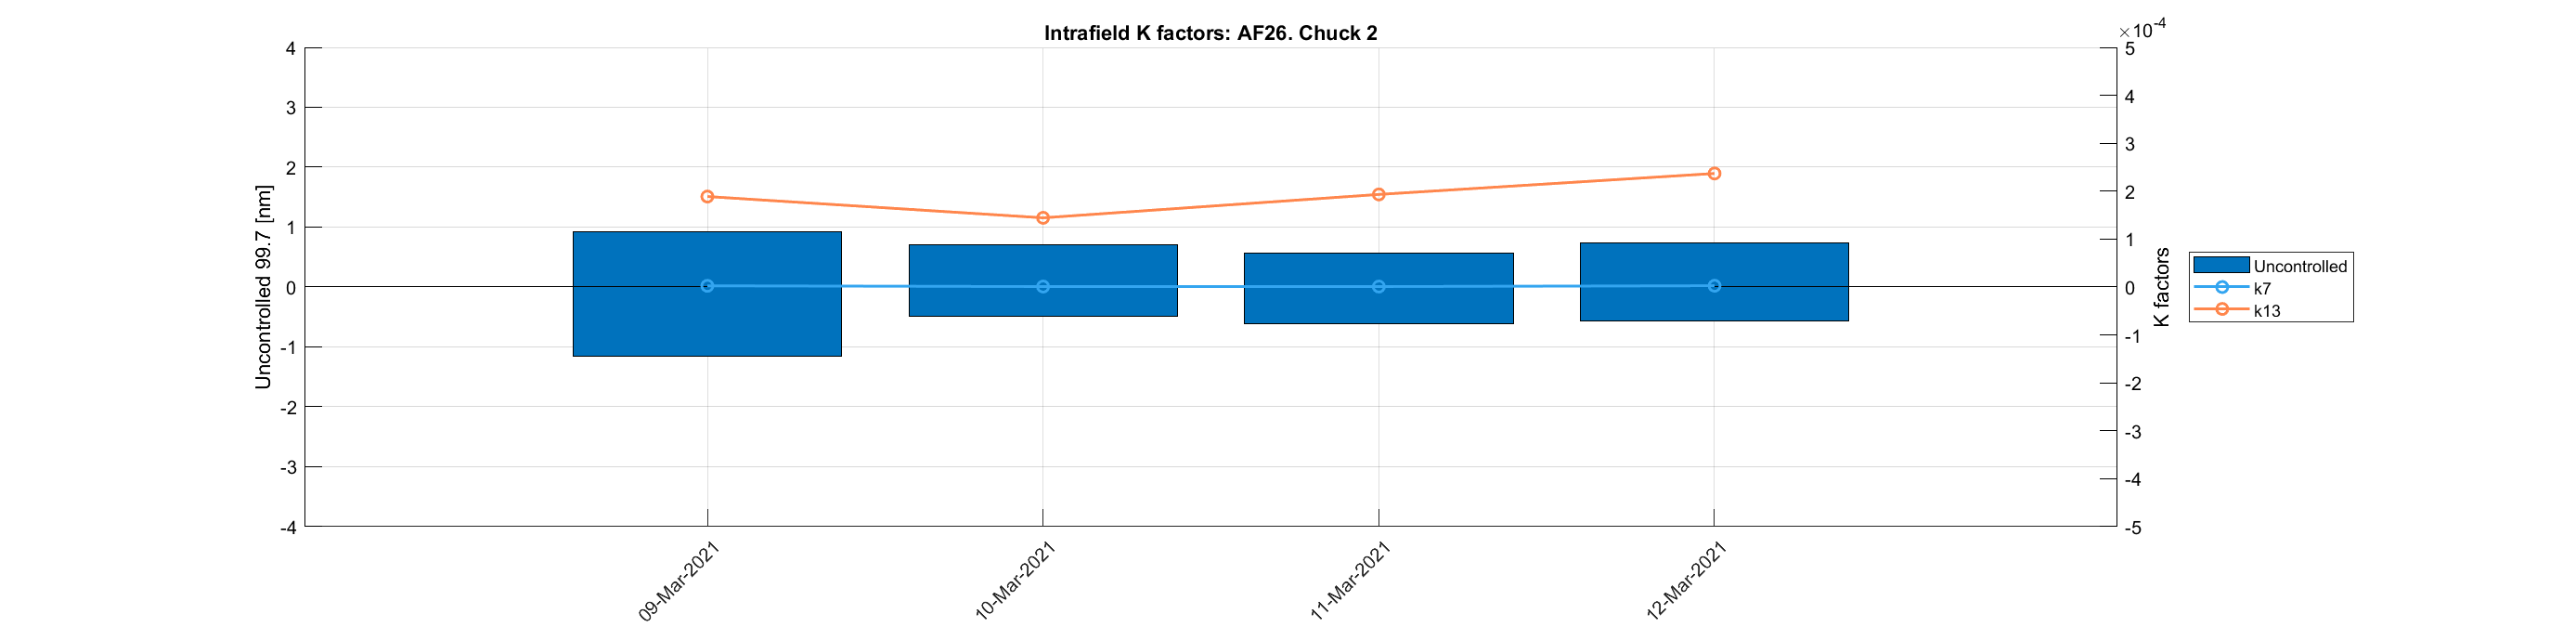

Kfactors = {'k7', 'k13'};
figs = uncontrolledIntraField(reRunOutputs, lot_dates, Kfactors, machineId);
setYaxis(figs, 'left', -4, 4);
setYaxis(figs, 'right', -5 * 10^-4,  5 * 10^-4);
ppt.insertFigures('Intrafield trend plots', [machineId ' chuck 1'], figs(1));
ppt.insertFigures('Intrafield trend plots', [machineId ' chuck 2'], figs(2));

close(figs(1), figs(2));

Finally, the ppt may be closed.

ppt.closeFile;